# **Name - Vinay Patil**

# **Net ID - vpatil3**

# **Question (1)**

**1(a)** I created a histogram of the image to see the image intensity distribution, which showed different clusters of the intensities. Since the main aim was to emphasize the exudates/bright spots, I selected the following window,

Width: 80, Center:180  

**1(b)** Since choosing weights depends on the part we are interested on, I first looked at each channels of the original image and determined the order of influence each channel had on the exudates. Then based on empirical experiments I came up with the 0.1, 0.6 and 0.3 weights respectively for RGB.

**1(c)**

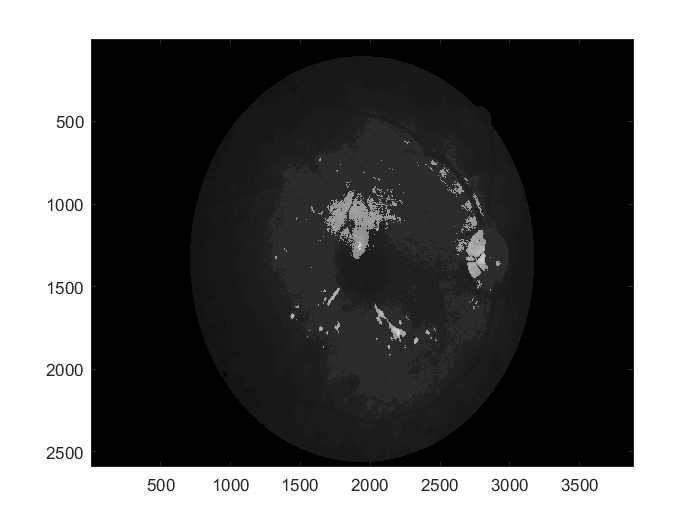

colorImg = imread('1008_right.jpeg');
colorImg(colorImg<100) = 0;
colorImg(colorImg>200) = 255;
grayImg = 0.1*colorImg(:,:,1)+0.6*colorImg(:,:,2)+0.3*colorImg(:,:,3); 
imagesc(grayImg)
colormap('gray');

# **Question (2)**

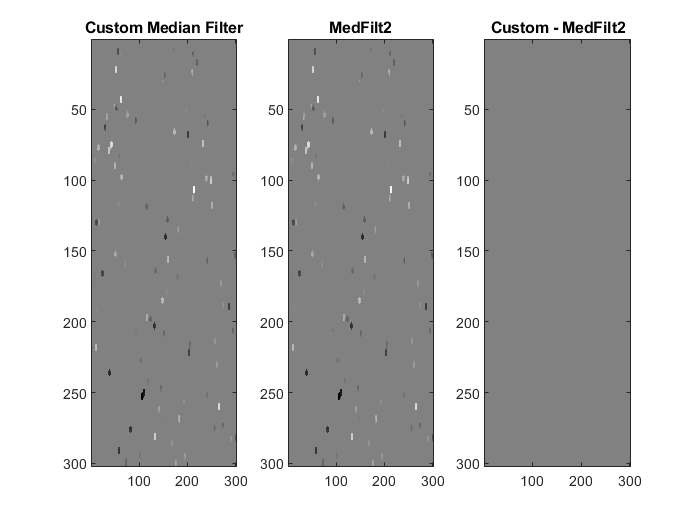

load('medfilt_problem_dat.mat');
dims = size(dat);
temp = zeros(dims(1)+2,dims(2)+2);
temp(2:dims(1)+1,2:dims(2)+1) = dat;
FilteredImage33 = zeros(dims(1),dims(2));

tempdims = size(temp);

for x = 2:tempdims(1)-1
    for y = 2:tempdims(2)-1
        Neighborhood = temp(x-1:x+1,y-1:y+1);
        FilteredImage33(x-1,y-1) = median(Neighborhood(:));      
    end
end
medianFilter = medfilt2(dat);
subplot(1,3,1)
imagesc(FilteredImage33)
title('Custom Median Filter')
subplot(1,3,2)
imagesc(medianFilter)
title('MedFilt2')
subplot(1,3,3)
imagesc(FilteredImage33-medianFilter)
title('Custom - MedFilt2')

**2(a)** Looking at the difference image and comparing the values of the both the matrices, I can say that both images are the same. This is because by default the medfilt2 makes use of 3X3 window and pads zeros at the boundary.

**2(b)** 11X11 is the minimum filter size that removes all of the salt and pepper.

**2(c)** 3X3 is the minimum filter size that gurantees the removal of an isolated piece of salt or pepper. This is because in the case of an isolated pixel, window of size 3X3 around it will have all zeros or equal numbers except the central pixel and hence the median of the 9 numbers will turn out to be zero/background. We didn't get this result in the previous part because not all of the noise is isolated and hence 3X3 on the whole image will remove isolated ones but the chunk's will survive.

# **Question (3)**

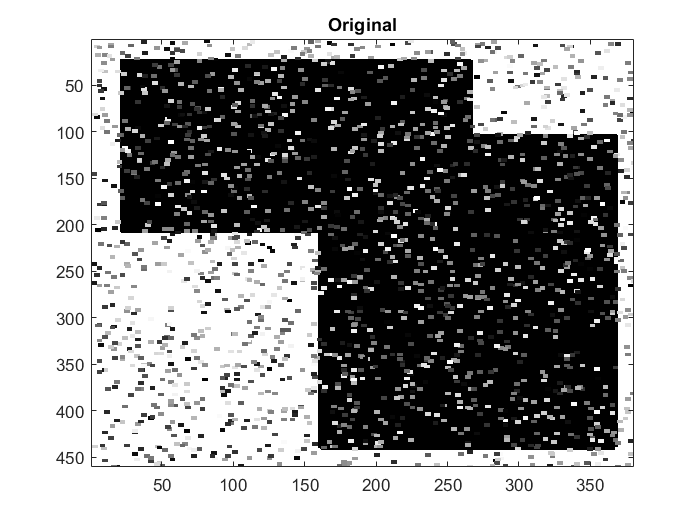

load('dat_hough.mat');
img = dat_hough;
figure
colormap('gray')
imagesc(img)
title('Original')

**Preprocessing Step** - I applied Median filter to get rid of the noise and make the edges crisp. The result can be seen in the Image below. I tried using median filters with higher windows as well, but as the window size increased, the edges were getting distorted and hence I found 9X9 to be the best possible filter size.

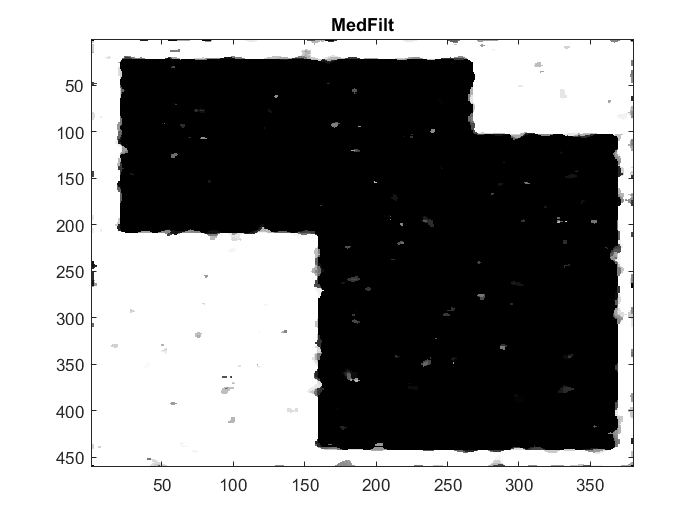

img1 = medfilt2(img,[9,9]);
figure
colormap('gray')
imagesc(img1)
title('MedFilt')

**Preprocessing Step** - Applied convolution using the sobel matrix, then applied threshold to get edge points of the image (Binarized the image - Which is the most ideal input to hough transform function)

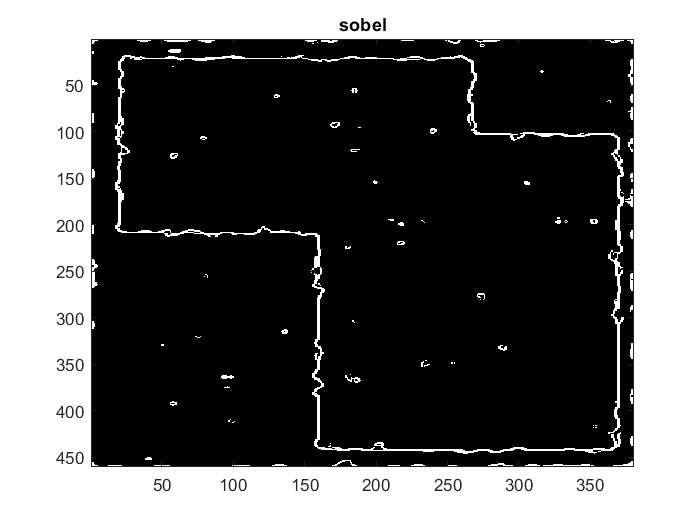

ksx = reshape([-1 -2 -1 0 0 0 1 2 1], 3, 3 );
ksy = ksx';

gx = conv2(img1, ksx, 'same');
gy = conv2(img1, ksy, 'same');

len_grad = sqrt(gx.^2 + gy.^2);
edge_sol = len_grad>80;

figure
colormap('gray')
imagesc(edge_sol)
title('sobel')

**Preprocessing Step** - Trimmed the boundary of the image which was introduced by the median filter because of the default 0 - padding

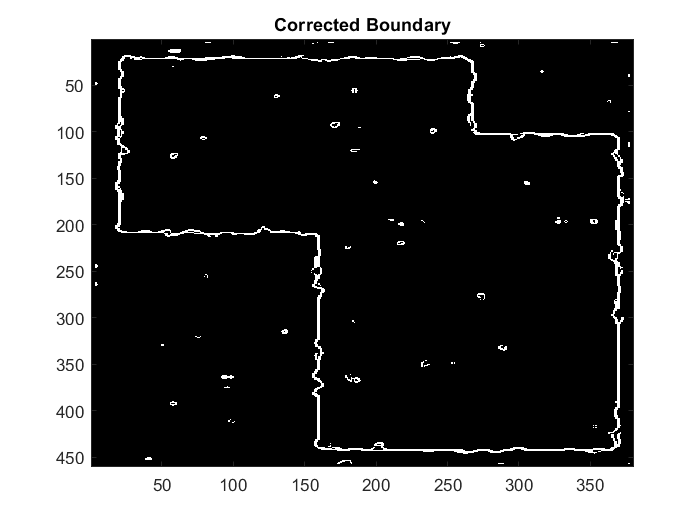

edge_sol(:,[1,2,3,end-2,end-1,end]) = 0;
edge_sol([1,2,3,end-2,end-1,end],:) = 0;

figure
colormap('gray')
imagesc(edge_sol)
title('Corrected Boundary')

Applied hough transform on the preprocessed image

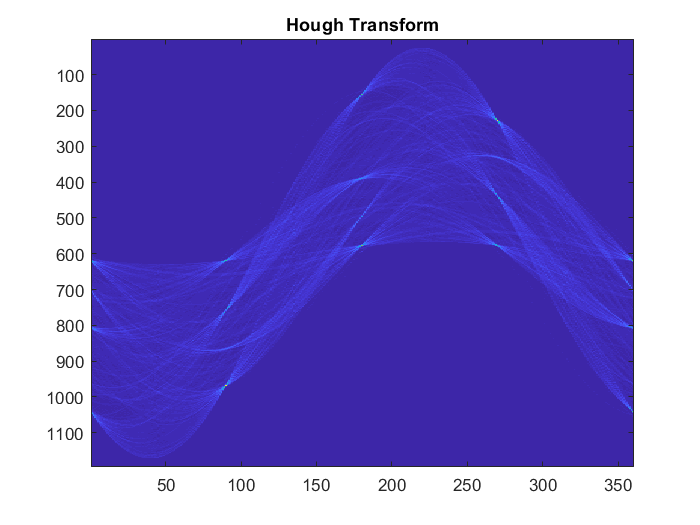

[himg, theta, r] = hough_trans(edge_sol);
figure
imagesc(himg)
title('Hough Transform')

Drawing the edge lines through the edge points

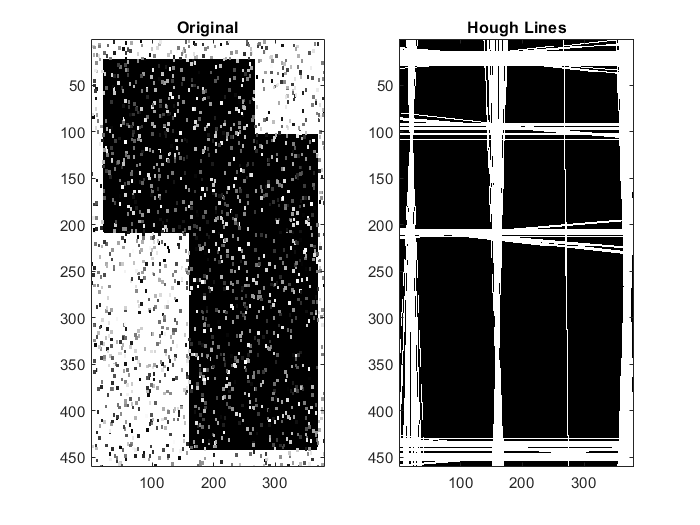

maxint=max(max(himg));

[i, j] = find(himg > 0.21*maxint);

theta_rad = theta*pi/180;
theta_sol = theta_rad(j);
r_sol = r(i);
slopes = -1*cos(theta_sol)./sin(theta_sol);
intercepts = r_sol./sin(theta_sol);

img_lines = zeros(size(img1));
num_sol = length(theta_sol);
for sol=1:num_sol
    if round(sin(theta_sol(sol)),1)==0 && abs(r_sol(sol))<size(img1,1) && abs(r_sol(sol))>0
        img_lines(abs(r_sol(sol)), :) = 1;
    else
        xval = [1:0.01:size(img1,1)]';
        yval = intercepts(sol) + slopes(sol)*xval;
        r_yvals = round(yval);
        r_xval = round(xval);
        [ind_keep] = find(r_yvals > 0 & r_yvals < size(img1,2));
        for loc=1:length(ind_keep)
          img_lines(r_xval(ind_keep(loc)), r_yvals(ind_keep(loc))) = 1;
        end
    end
end


figure
subplot(1, 2, 1)
imagesc(img)
title('Original')
subplot(1, 2, 2)
imagesc(img_lines)
title('Hough Lines')
colormap(gray)

Combining the hough lines and the original image

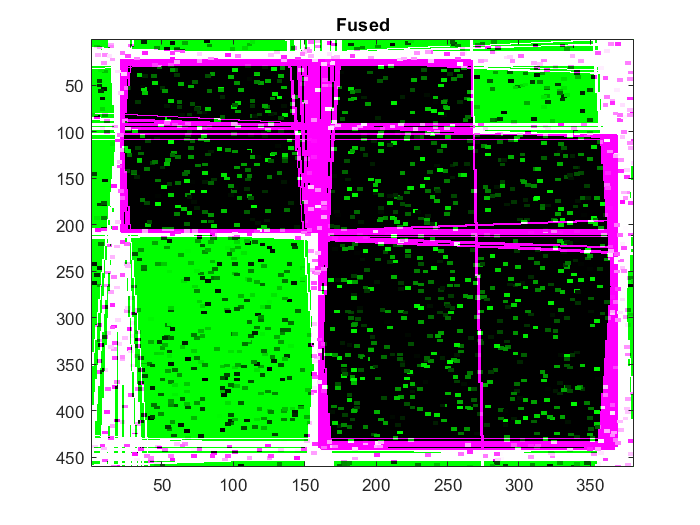

fused_img = imfuse(img, img_lines);
figure
imagesc(fused_img)
title('Fused')

# Question (4)

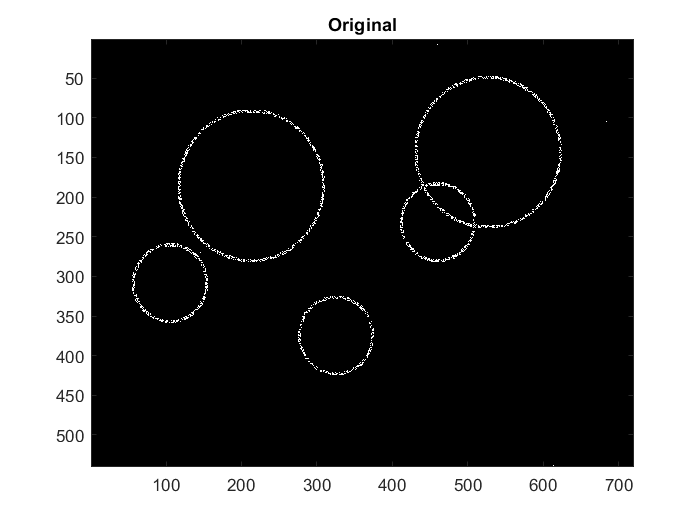

load('img_circle.mat');
img = img_circle;
figure
colormap('gray')
imagesc(img)
title('Original')

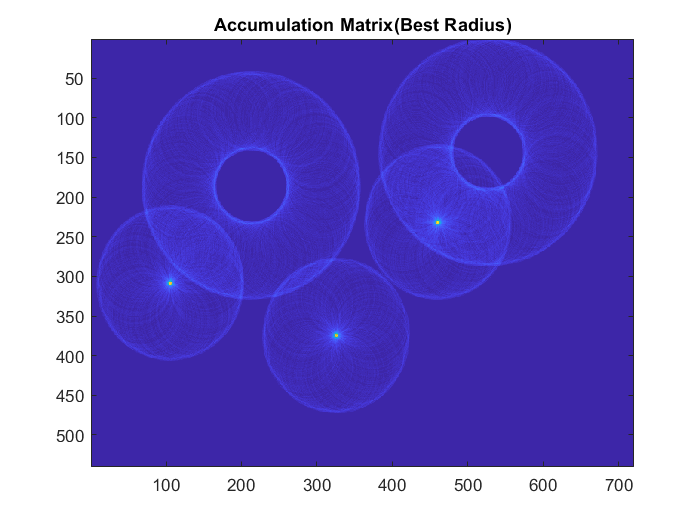

[himg, theta, radius] = circle_hough_trans(img);
figure
imagesc(himg(:,:,1))
title('Accumulation Matrix(Best Radius)')

rad1AccMatrix = himg(:,:,1);
rad2AccMatrix = himg(:,:,2);
rad3AccMatrix = himg(:,:,3);

radius1MaxValue = max(rad1AccMatrix(:));
radius2MaxValue = max(rad2AccMatrix(:));
radius3MaxValue = max(rad3AccMatrix(:));

winning_radius = radius(1)

winning_radius = 48

[i, j] = find(himg(:,:,1) >0.85*radius1MaxValue);

centerEstimates = [i, j]

centerEstimates =    308   105
   309   105
   309   106
   374   326
   375   327
   231   460
   232   460
   233   460
   231   461
   232   461


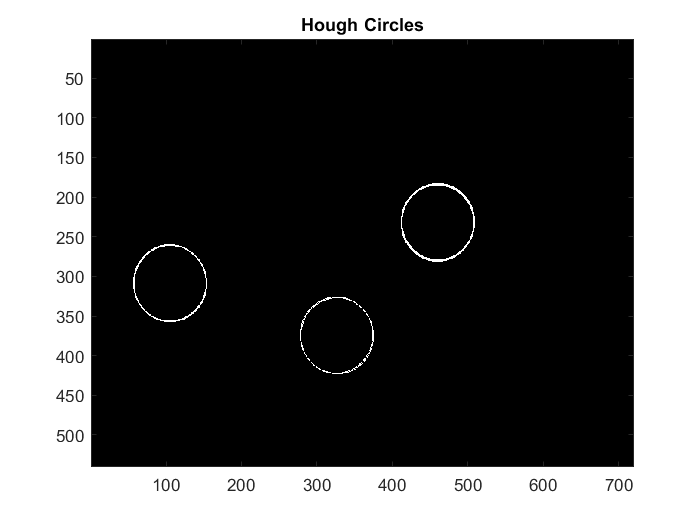

i_rng = size(img, 1);
j_rng = size(img, 2);
hough_circles=zeros(i_rng, j_rng);
theta = 1:360;

for t=1:length(centerEstimates)
    for ang=theta
        theta_loop=ang*pi/180;
        xloop = round(centerEstimates(t,1)-(winning_radius*cos(theta_loop)));
        yloop = round(centerEstimates(t,2)-(winning_radius*sin(theta_loop)));
        if xloop>0 && yloop>0 && xloop<=i_rng && yloop<=j_rng
                hough_circles(xloop,yloop) = 1;
        end
    end
end
figure
imagesc(hough_circles)
title('Hough Circles')
colormap(gray)

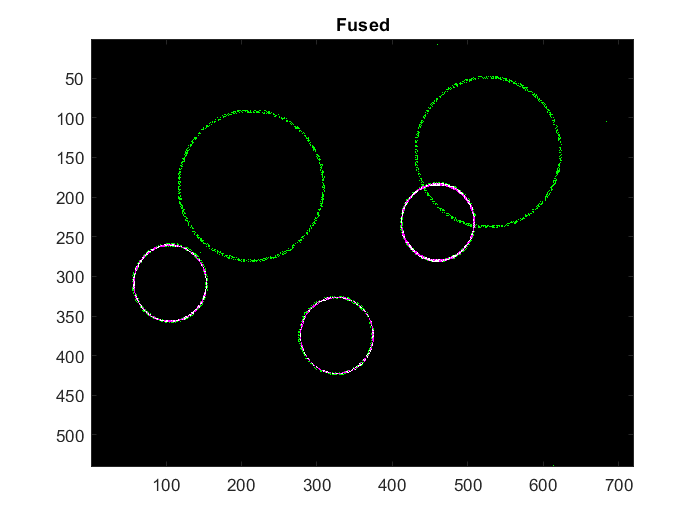

fused_img = imfuse(img, hough_circles);
figure
imagesc(fused_img)
title('Fused')